% GitHub Repositry: https://github.com/zizowasfy/Trajectory_Planning.git
clear all

## Forward Kinematics


$$T_{H\;} =R_z \left(\theta_1 \right)\;\cdot T_z \left(\mathrm{L1}\right)\cdot R_y \left(\theta_2 \right)\cdot T_x \left(\mathrm{L2}\right)\cdot {R_y \left(\theta_3 \right)\cdot \;T}_x \left(\mathrm{L3}\right)$$



syms theta1 theta2 theta3
[L1,L2,L3] = deal(1,1,1);
theta1 = deg2rad(25); theta2 = deg2rad(20) ; theta3 = deg2rad(30);
% theta1 = 0.7854 ; theta2 = -0.7854 ; theta3 = 1.5708;
T_H = RotR("z",theta1) * Trans("z",L1) * RotR("y",theta2) * Trans("x",L2) * RotR("y",theta3) * Trans("x",L3)

T_H =     0.5826   -0.4226    0.6943    1.4342
    0.2717    0.9063    0.3237    0.6688
   -0.7660         0    0.6428   -0.1081
         0         0         0    1.0000


% T_H = simplify(T_H)



## Inverse Kinematics

syms x y z
x = T_H(1,4) ; y = T_H(2,4) ; z = T_H(3,4) ;
% x = 1 ; y = 1 ; z = 1 ;
m = 1 ;     % +1 elbow up ; -1 elbow down
Y = z - L1; 
X = sqrt(x^2+y^2);
theta1 = atan2(y,x)

theta1 = 0.4363

theta2 = atan2(Y,X) - m * acos((X^2 + Y^2 + L2^2 - L3^2)/(2*L2*sqrt(X^2 + Y^2)))

theta2 = -0.8727

theta3 = m * (pi - acos((-(x^2 + y^2) - (z-L1)^2 + L2^2 + L3^2)/(2 * L2 * L3)))

theta3 = 0.5236

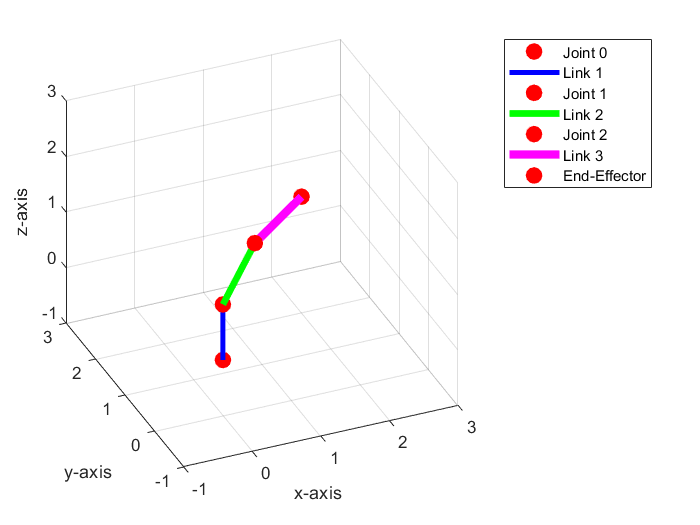

% theta2 = -m * atan((L3*cos(theta3))/(L2+L3*sin(theta3))) + atan((z-L1)/(sqrt(x^2+y^2)));
robot([L1 L2 L3],[theta1 theta2 theta3])

## 1) Geometrical Approach (Skew Theory)

syms theta1 theta2 theta3
T00 = eye(4);
T01 = RotR("z",theta1) * Trans("z",L1);
T02 = RotR("z",theta1) * Trans("z",L1) * RotR("y",theta2) * Trans("x",L2);
T03 = T_H;

% defining the translation vector of each joint
On = T_H(1:3,4);    % Tranlation vector of the FK 
O0 = T00(1:3,4);
O1 = T01(1:3,4);
O2 = T02(1:3,4);

% defining the u vector from the R matrix of each joint
u1 = T00(1:3,3);    % rotation around z-axis therefore extract the 3rd column
u2 = T01(1:3,2);    % rotation around y-axis therefore extract the 2nd column
u3 = T03(1:3,2);    % rotation around y-axis therefore extract the 2nd column

J1(1:3,1) = cross(u1,(On - O0));
J1(4:6,1) = u1;
% J1 = simplify(J1)

J2(1:3,1) = cross(u2,(On - O1));
J2(4:6,1) = u2;
% J2 = simplify(J2)

J3(1:3,1) = cross(u3,(On - O1));
J3(4:6,1) = u3;
% J3 = simplify(J3)

J_skew = simplify([J1 J2 J3])

$$J\_skew = \left(\begin{array}{ccc} -\frac{6023880152072045}{9007199254740992} & -\frac{9980558517229107\,\cos\left(\theta_{1}\right)}{9007199254740992} & -\frac{81474241683950923614649076843397}{81129638414606681695789005144064}\\ \frac{807390792152417}{562949953421312} & -\frac{9980558517229107\,\sin\left(\theta_{1}\right)}{9007199254740992} & -\frac{75984125679195051525579688589961}{162259276829213363391578010288128}\\ 0 & -\frac{807390792152417\,\cos\left(\theta_{1}\right)}{562949953421312}-\frac{6023880152072045\,\sin\left(\theta_{1}\right)}{9007199254740992} & -\frac{256772097792986276259156700981559}{162259276829213363391578010288128}\\ 0 & -\sin\left(\theta_{1}\right) & -\frac{7613213784381523}{18014398509481984}\\ 0 & \cos\left(\theta_{1}\right) & \frac{8163294823962471}{9007199254740992}\\ 1 & 0 & 0 \end{array}\right)$$

## 2)

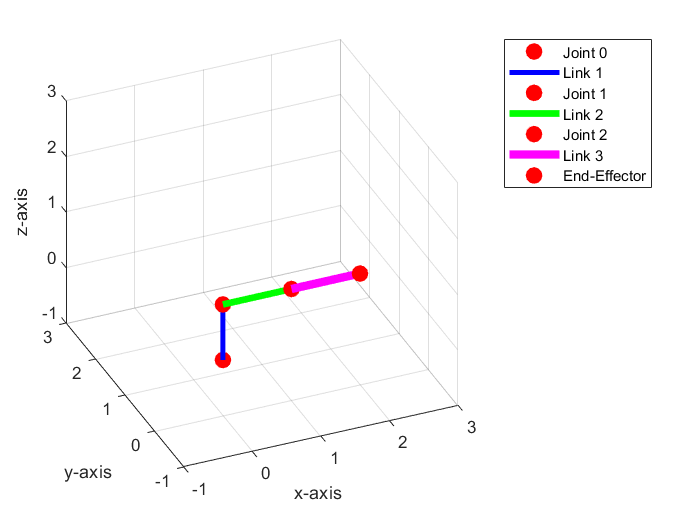

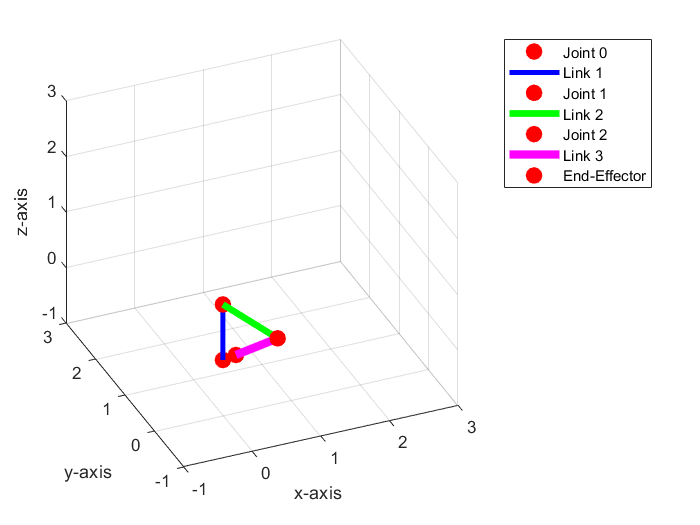

% clear all
q0 = [0 0 0]; qf = [2 3 4];
t0 = 0;       tf = 2;
v0 = 0;       vf = 0;
a0 = 0;       af = 0;

ts = t0:0.1:tf;
% 6 constraints 5th order polynomial

A = [1 t0 t0^2  t0^3    t0^4    t0^5;
     0 1  2*t0  3*t0^2  4*t0^3  5*t0^4;
     0 0  2     6*t0    12*t0^2 20*t0^3;
     1 tf  tf^2  tf^3    tf^4    tf^5;
     0 1  2*tf  3*tf^2  4*tf^3  5*tf^4;
     0 0  2     6*tf    12*tf^2 20*tf^3];
 
% b = zeros(6,3);
for i = 1:length(q0)
    c = [q0(i) v0 a0 qf(i) vf af]';
    b(1:6,i) = A\c ;
%     syms t 
    q(i,1:length(ts)) = b(1,i) + b(2,i).*ts + b(3,i).*ts.^2 + b(4,i).*ts.^3 + b(5,i).*ts.^4 + b(6,i).*ts.^5; 
end
% visualizing the Robot's Path
figure
for i = 1:length(q)
    clf
    robot([L1,L2,L3],q(:,i));
    pause(0.01)
end


figure
% Joint 1 (theta1)
syms t
q = b(1,1) + b(2,1).*t + b(3,1).*t.^2 + b(4,1).*t.^3 + b(5,1).*t.^4 + b(6,1).*t.^5;
qd = diff(q,t);
qdd = diff(q,t,2);
subplot(3,3,1)
plot(ts,subs(q,t,ts)),xlabel('Time (s)'),ylabel('Angle (Rad)'),title('theta1')
subplot(3,3,4)
plot(ts,subs(qd,t,ts)),xlabel('Time (s)'),ylabel('Velocity (Rad/s)'),title('theta1')
subplot(3,3,7)
plot(ts,subs(qdd,t,ts)),xlabel('Time (s)'),ylabel('Acceleration (Rad/s^2)'),title('theta1')

% Joint 2 (theta2)
syms t
q = b(1,2) + b(2,2).*t + b(3,2).*t.^2 + b(4,2).*t.^3 + b(5,2).*t.^4 + b(6,2).*t.^5

$$q = \frac{9\,t^{5}}{16}-\frac{45\,t^{4}}{16}+\frac{15\,t^{3}}{4}-\frac{t}{562949953421312}$$

qd = diff(q,t)

$$qd = \frac{45\,t^{4}}{16}-\frac{45\,t^{3}}{4}+\frac{45\,t^{2}}{4}-\frac{1}{562949953421312}$$

qdd = diff(q,t,2)

$$qdd = \frac{45\,t^{3}}{4}-\frac{135\,t^{2}}{4}+\frac{45\,t}{2}$$

subplot(3,3,2)
plot(ts,subs(q,t,ts)),xlabel('Time (s)'),ylabel('Angle (Rad)'),title('theta2')
subplot(3,3,5)
plot(ts,subs(qd,t,ts)),xlabel('Time (s)'),ylabel('Velocity (Rad/s)'),title('theta2')
subplot(3,3,8)
plot(ts,subs(qdd,t,ts)),xlabel('Time (s)'),ylabel('Acceleration (Rad/s^2)'),title('theta2')

% Joint 3 (theta3)
syms t
q = b(1,3) + b(2,3).*t + b(3,3).*t.^2 + b(4,3).*t.^3 + b(5,3).*t.^4 + b(6,3).*t.^5

$$q = \frac{3\,t^{5}}{4}-\frac{15\,t^{4}}{4}+5\,t^{3}+\frac{t}{281474976710656}$$

qd = diff(q,t)

$$qd = \frac{15\,t^{4}}{4}-15\,t^{3}+15\,t^{2}+\frac{1}{281474976710656}$$

qdd = diff(q,t,2)

$$qdd = 15\,t^{3}-45\,t^{2}+30\,t$$

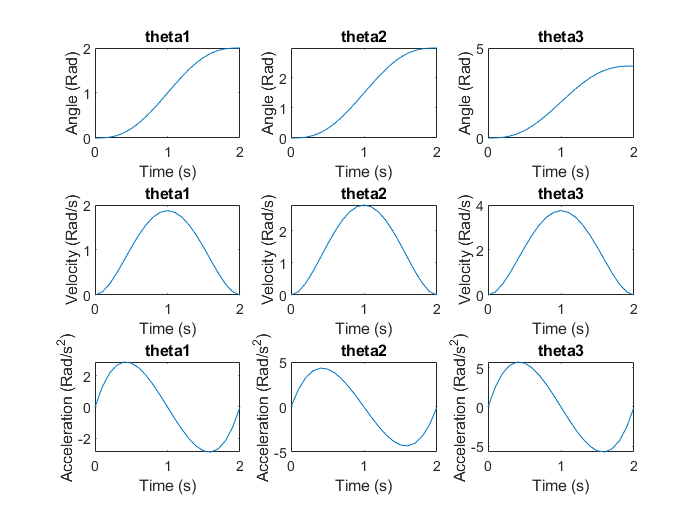

subplot(3,3,3)
plot(ts,subs(q,t,ts)),xlabel('Time (s)'),ylabel('Angle (Rad)'),title('theta3')
subplot(3,3,6)
plot(ts,subs(qd,t,ts)),xlabel('Time (s)'),ylabel('Velocity (Rad/s)'),title('theta3')
subplot(3,3,9)
plot(ts,subs(qdd,t,ts)),xlabel('Time (s)'),ylabel('Acceleration (Rad/s^2)'),title('theta3') 

## 3)

% clear all
clearvars -except J_skew theta1 theta2 theta3

q0 = [0 0 0]; qf = [2 3 4];
t0 = 0;       
v0 = 0;       vf = 0;
a0 = 0;       af = 0;
tcontontroller = 1/100 ; 
vmax = 1 ;              % MaxVelocity rad/s
amax = 10;              % Maxacceleration rad/s^2

% Adjusting the time, velcoities, accelerations of all joints for synchronization motion (all reach goal position at the same time)
for i = 1:length(q0)
    ta(i) = vmax/amax
    tf(i) = ((qf(i)-q0(i)/(vmax)) + ta(i))
    % Making sure that all values of ta and tf of the 3 joints coincide with the Controller frequency
    while rem(ta(i),tcontontroller) ~= 0 && rem(tf(i),tcontontroller) ~= 0
        if rem(ta(i),tcontontroller) ~= 0
            ta(i) = ta(i) + tcontontroller;
        elseif rem(tf(i),tcontontroller) ~= 0
            tf(i) = tf(i) + tcontontroller;        
        end
    end
    old_velocities(i) = (qf(i) - q0(i))/(tf(i)-ta(i));
    old_accelerations(i) = old_velocities(i) / ta(i);
end

ta = 0.1000

tf = 2.1000

ta =     0.1000    0.1000


tf =     2.1000    3.1000


ta =     0.1000    0.1000    0.1000


tf =     2.1000    3.1000    4.1000


old_velocities

old_velocities =     1.0000    1.0000    1.0000


old_accelerations

old_accelerations =    10.0000   10.0000   10.0000


%     velocities(i) = (qf(i) - q0(i))/(max(tf)-max(ta))
%     accelerations(i) = velocities(i) / max(ta)

 
%     taMax = max(ta)
%     tfMax = max(tf)

ts = 0:tcontontroller:max(tf);

% Computing the Coefficients
for i = 1:length(q0)
    
    velocities(i) = (qf(i) - q0(i))/(max(tf)-max(ta));
    accelerations(i) = velocities(i) / max(ta);
    % t0 --> ta:   ta
    a10(i) = q0(i);
    a11(i) = 0;
    a12(i) = 0.5*accelerations(i);
    
    
    % ta --> tf-ta:
    a20(i) = q0(i) + 0.5*accelerations(i)*ta(i)^2 - velocities(i)*max(ta);
    a21(i) = velocities(i);
    
    % tf-ta --> tf:
    a30(i) = qf(i) - 0.5 * accelerations(i) * max(tf)^2;
    a31(i) = accelerations(i) * max(tf);
    a32(i) = -0.5 * accelerations(i);
    
    coefficients(i,:) = [a10(i) a11(i) a12(i) a20(i) a21(i) a30(i) a31(i) a32(i)];


    q(i,:) = (coefficients(i,1) + coefficients(i,2) .* ts + coefficients(i,3) .* ts.^2) .* (ts<=max(ta)) ...
            + (coefficients(i,4) + coefficients(i,5) .* ts) .*(ts>max(ta)) .*(ts<=max(tf)-max(ta)) ...
            + (coefficients(i,6) + coefficients(i,7) .* ts + coefficients(i,8) .* ts.^2) .* (ts>max(tf)-max(ta)) .* (ts<=max(tf));
    
    qd(i,:) = (coefficients(i,2) + 2 * coefficients(i,3) .* ts) .* (ts<=max(ta)) ...
            + (coefficients(i,5)) .*(ts>max(ta)) .*(ts<=(max(tf)-max(ta))) ...
            + (coefficients(i,7) + 2 * coefficients(i,8) .* ts) .* (ts>(max(tf)-max(ta))) .* (ts<=max(tf));
    
    qdd(i,:) = (2 * coefficients(i,3)) .* (ts<=max(ta)) ...
            +  (0) .*(ts>max(ta)) .*(ts<=(max(tf)-max(ta))) ...
            + (2 * coefficients(i,8)) .* (ts>(max(tf)-max(ta))) .* (ts<=max(tf));

end
velocities

velocities =     0.5000    0.7500    1.0000


accelerations

accelerations =     5.0000    7.5000   10.0000


coefficients

coefficients =          0         0    2.5000   -0.0250    0.5000  -40.0250   20.5000   -2.5000
         0         0    3.7500   -0.0375    0.7500  -60.0375   30.7500   -3.7500
         0         0    5.0000   -0.0500    1.0000  -80.0500   41.0000   -5.0000


     
%visualizing the Robot's Path
figure
for i = 1:length(q(1,:))
    clf
    robot([1,1,1],q(:,i))
    pause(0.001)
end

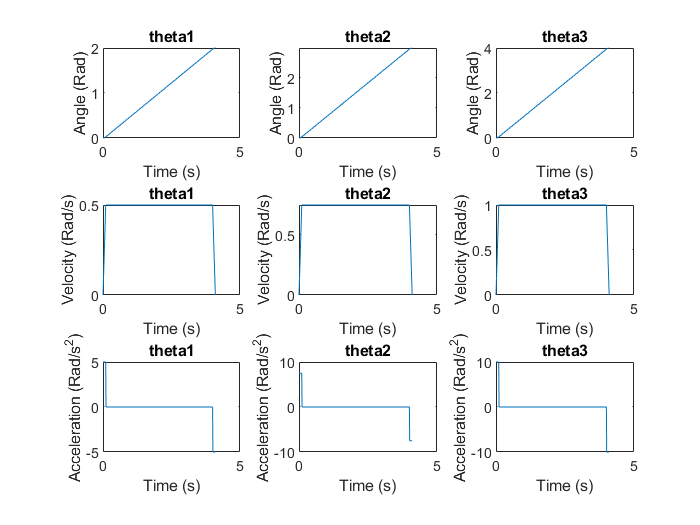


% syms t
% q1 = (coefficients(1,1) + coefficients(1,2) .* t + coefficients(1,3) .* t.^2) .* (ts<=max(ta)) ...
%      +(coefficients(1,4) + coefficients(1,5) .* t) .*(ts>max(ta)) .*(ts<=max(tf)-max(ta)) ...
%      +(coefficients(1,6) + coefficients(1,7) .* t + coefficients(1,8) .* t.^2) .* (ts>max(tf)-max(ta)) .* (ts<=max(tf));
% A = [1 t0 t0^2   0 0 0 0     0;
%      0 1 2*t0    0 0 0 0     0;
%      0 1 2*ta(2) 0 0 0 0     0;
%      0 1 2*ta(2) 0 -1 0 0    0;
%      0 0 0       0 1 0 0     0;
%      0 0 0       0 1 0 -1    -2*(tf(2)-ta(2));
%      0 0 0       0 0 1 tf(2) tf(2)^2;
%      0 0 0       0 0 0 1     2*tf(2)]
% 
% c = [q0(2) 0 velocities(2) 0 velocities(2) 0 qf(2) 0]';
% b = A\c
 
% 
figure
% Joint 1 (theta1)
% syms t Real
% q1 = (coefficients(1,1) + coefficients(1,2) .* t + coefficients(1,3) .* t.^2) .* (t<=max(ta)) ...
%    + (coefficients(1,4) + coefficients(1,5) .* t) .*(t>max(ta)) .*(t<=(max(tf)-max(ta))) ...
%    + (coefficients(1,6) + coefficients(1,7) .* t + coefficients(1,8) .* t.^2) .* (t>(max(tf)-max(ta))) .* (t<=max(tf));

% q1 = (coefficients(1,1) + coefficients(1,2) .* ts + coefficients(1,3) .* ts.^2) .* (ts<=max(ta)) ...
%    + (coefficients(1,4) + coefficients(1,5) .* ts) .*(ts>max(ta)) .*(ts<=(max(tf)-max(ta))) ...
%    + (coefficients(1,6) + coefficients(1,7) .* ts + coefficients(1,8) .* ts.^2) .* (ts>(max(tf)-max(ta))) .* (ts<=max(tf));
% 
% 
% q1d = (coefficients(1,2) + 2 * coefficients(1,3) .* t) .* (t<=max(ta)) ...
%     +  coefficients(1,5) .*(t>max(ta)) .*(t<=max(tf)-max(ta)) ...
%     + (coefficients(1,7) + 2 * coefficients(1,8) .* t) .* (t>(max(tf)-max(ta))) .* (t<=max(tf));

subplot(3,3,1)
plot(ts,q(1,:)),xlabel('Time (s)'),ylabel('Angle (Rad)'),title('theta1')
subplot(3,3,4)
plot(ts,qd(1,:)),xlabel('Time (s)'),ylabel('Velocity (Rad/s)'),title('theta1')
subplot(3,3,7)
plot(ts,(qdd(1,:))),xlabel('Time (s)'),ylabel('Acceleration (Rad/s^2)'),title('theta1')

% Joint 2 (theta2)
subplot(3,3,2)
plot(ts,q(2,:)),xlabel('Time (s)'),ylabel('Angle (Rad)'),title('theta2')
subplot(3,3,5)
plot(ts,qd(2,:)),xlabel('Time (s)'),ylabel('Velocity (Rad/s)'),title('theta2')
subplot(3,3,8)
plot(ts,qdd(2,:)),xlabel('Time (s)'),ylabel('Acceleration (Rad/s^2)'),title('theta2')

% Joint 3 (theta3)
subplot(3,3,3)
plot(ts,q(3,:)),xlabel('Time (s)'),ylabel('Angle (Rad)'),title('theta3')
subplot(3,3,6)
plot(ts,qd(3,:)),xlabel('Time (s)'),ylabel('Velocity (Rad/s)'),title('theta3')
subplot(3,3,9)
plot(ts,qdd(3,:)),xlabel('Time (s)'),ylabel('Acceleration (Rad/s^2)'),title('theta3')

## 4)

% clear all 
% close all
% L1 = 1 ; L2 = 1 ; L3 = 1;
p1 = [1 0 1];   p2 = [sqrt(2)/2 sqrt(2)/2 1.2];     % Defining Points in 3D Space
p12 = p2 - p1         % Vector of the Targeted LINE

p12 =    -0.2929    0.7071    0.2000


p = sqrt((p1(1)-p2(1))^2 + (p1(2)-p2(2))^2 + (p1(3)-p2(3))^2)    % The length of the Line in 3D Space

p = 0.7911

figure
plot3([p1(1) p2(1)],[p1(2) p2(2)],[p1(3) p2(3)]),xlabel("X-axis"),ylabel("Y-axis"),zlabel("Z-axis")     % Ploting the Target LINE
hold on

tcontroller = 1/100 ; n = 2;
lvmax = 1 ;              % Linear MaxVelocity in the xyz direction m/s
lamax = 10;              % Linear Maxacceleration in the xyz direction m/s^2

% IT IS ASSUMED that the lvmax and lamax are linear velocities and accelerations in the XYZ space not in a particular axis of them

N = 100 ; 
% ------------ Adjusting the time with the controller frequency (100 Hz)
ta = lvmax/lamax 

ta = 0.1000

if rem(ta,tcontroller)~=0
    ta_adj = round(ta,n) + 10^-n;
else
    ta_adj = round(ta,n);
end
tf = (p/(lvmax)) + ta

tf = 0.8911


if rem(tf,tcontroller)~=0
    tf_adj = round(tf,n) + 10^-n;
else
    tf_adj = round(tf,n);
end
ta_adj

ta_adj = 0.1000

tf_adj

tf_adj = 0.9000

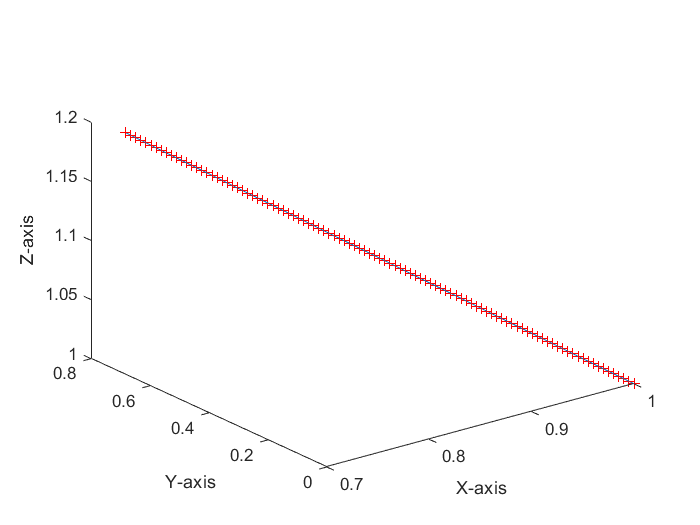

% ------------ % Segmenting the Target Line into points
lsegments = 0:0.01:1 ;       % 100 segments
for i = 1:length(lsegments)
    points(1,i) = lsegments(i) * p12(1) + p1(1);        % x 
    points(2,i) = lsegments(i) * p12(2) + p1(2);        % y 
    points(3,i) = lsegments(i) * p12(3) + p1(3);        % z 
    plot3(points(1,i),points(2,i),points(3,i),'r+')

    hold on
end

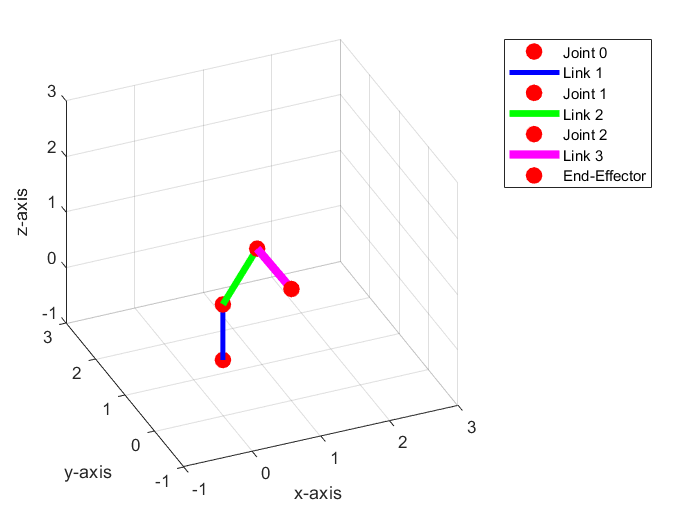

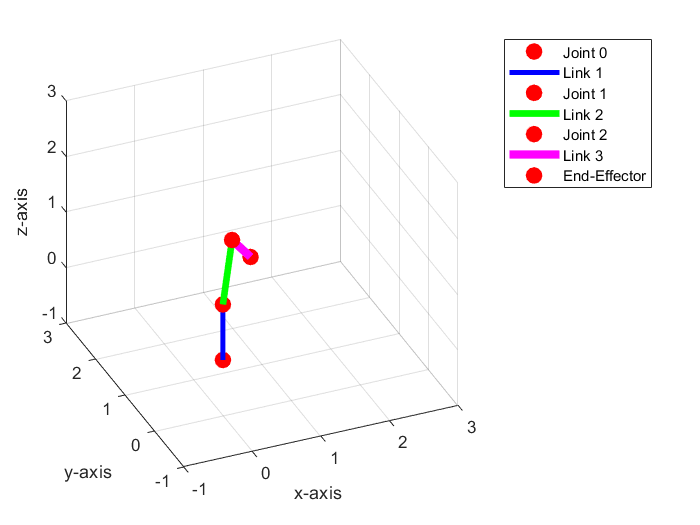

% ------------ % Use the Inverse Kinematics to solve for Joint angles of these Points

for i = 1:length(points)
    [q1,q2,q3] = IK(points(1,i),points(2,i),points(3,i));      % elbow up configuration
    joints(:,i) = [q1,-q2,-q3]';
end

figure
% Visualizing the Robot
for i = 1:5:length(joints(1,:))
    clf
    robot([1,1,1],joints(:,i));
    pause(0.01)
end


% ------------ % Compute the Jacobian of each Joint configuration

for i = 1:length(joints(1,:))
    joints_jacob(:,:,i) = subs(J_skew,[theta1,theta2,theta3],[joints(1,i),joints(2,i),joints(i)]);
end


% ------------ % Get the Velocities of these points from the Trapezoidal Velocity Profile in the Cartesian Space   (Figure 1)

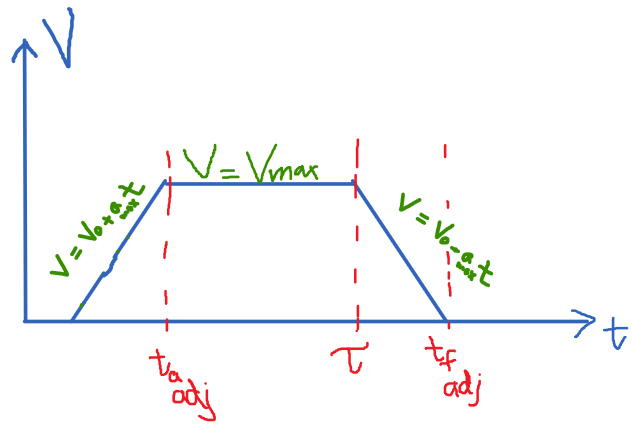

                                                         Figure 1                                                                                                           Figure 2

## - Next we need to get the Velocities of these points from the Trapezoidal Velocity Profile in the Cartesian Space (Figure 1).

% ------------ % Get the Velocities of know points from the Trapezoidal Velocity Profile in the Cartesian Space   (Figure 1)
% @ t0 , ta_adj , taw , tf
% @ t0  point 1
% velocity = 0 ; acceleration = 0 ; time = 0;
xyzdist1 = 0;
xyzpointind1 = 1;
    jointofpoints(:,1) = joints(:,xyzpointind1);                                   % Joint configuration of the 4 points on the xyz Trapezoidal profile
    jacobofpoints(:,:,1) = joints_jacob(1:3,1:3,xyzpointind1);                     % Jacobian of the 4 points on the xyz Trapezoidal profile
    jointvelofpoints(:,1) = jacobofpoints(:,:,1) \ [0 0 0]';                       % Joint Velocities at the 4 points



% @ ta_adj  point 2
% velocity = lvmax; acceleration = lamax; time = ta_adj;
xyzdist2 = 0.5 * lamax * ta_adj^2;       % distance covered along the LINE in the XYZ space % derived from Newton's third equation of motion: x = v0*t + 0.5*a*t^2
% pointind = find(lsegments == xyzdist)    
xyzpointind2 = 6;        % 6th point in the lsegments

    jointofpoints(:,2) = joints(:,xyzpointind2);                                   % Joint configuration of the 4 points on the xyz Trapezoidal profile
    jacobofpoints(:,:,2) = joints_jacob(1:3,1:3,xyzpointind2);                     % Jacobian of the 4 points on the xyz Trapezoidal profile
    jointvelofpoints(:,2) = jacobofpoints(:,:,2) \ [1 1 1]';                       % Joint Velocities at the 4 points



% @ taw = tf_adj - ta_adj point 3,
% velocity = lvmax; acceleration = -lamax; time = tf_adj - ta_adj;
xyzdist3 = p - xyzdist2;
xyzpointind3 = 96 ;

    jointofpoints(:,3) = joints(:,xyzpointind3);                                   % Joint configuration of the 4 points on the xyz Trapezoidal profile
    jacobofpoints(:,:,3) = joints_jacob(1:3,1:3,xyzpointind3);                     % Jacobian of the 4 points on the xyz Trapezoidal profile
    jointvelofpoints(:,3) = jacobofpoints(:,:,3) \ [1 1 1]';                       % Joint Velocities at the 4 points



% @ ft point 4
% velocity = 0 ; acceleration = 0 ; time = ft;
xyzdist = p;
xyzpointind4 = length(lsegments);

    jointofpoints(:,4) = joints(:,xyzpointind4);                                   % Joint configuration of the 4 points on the xyz Trapezoidal profile
    jacobofpoints(:,:,4) = joints_jacob(1:3,1:3,xyzpointind4);                     % Jacobian of the 4 points on the xyz Trapezoidal profile
    jointvelofpoints(:,4) = jacobofpoints(:,:,4) \ [0 0 0]';                       % Joint Velocities at the 4 points



xyzpointsind = [xyzpointind1 xyzpointind2 xyzpointind3 xyzpointind4];
xyzpointsvel = [lvmax lvmax lvmax];

% ------------ % Computing the Joint Velocities of these 4 points




